### Growth in 10% Compost Wastewater

This experiment measured the growth of R. Palustris in 10% compost wastewater in 8 test tubes labelled A through H. There is no difference between samples. Data collection began on 03/08. Optical density was measured approximately every 12 hours until growth plateaued on [].

clear
clf

data = readmatrix('rpalus_10percent_03112023.csv');
num_datapoints = (length(data));

% label data from csv
time = data(:, 1) / 60;     % hours
A = data(:, 2); % optical density
B = data(:, 3); % optical density
C = data(:, 4); % optical density
D = data(:, 5); % optical density
E = data(:, 6); % optical density
F = data(:, 7); % optical density
G = data(:, 8); % optical density
H = data(:, 9); % optical density

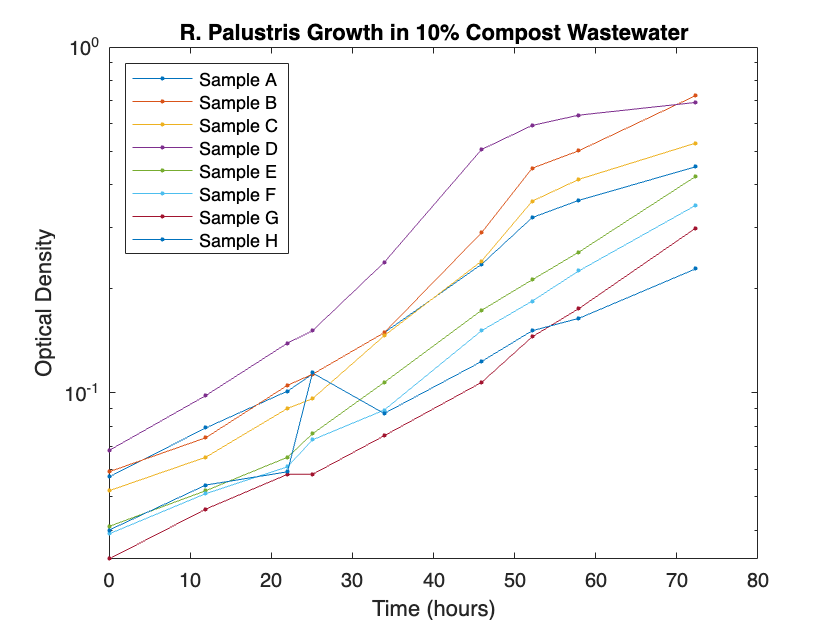

figure
semilogy(time, A, '.    -');
hold on
semilogy(time, B, '.-');
semilogy(time, C, '.-');
semilogy(time, D, '.-');
semilogy(time, E, '.-');
semilogy(time, F, '.-');
semilogy(time, G, '.-');
semilogy(time, H, '.-');

title("R. Palustris Growth in 10% Compost Wastewater")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Sample A","Sample B","Sample C","Sample D", ...
        "Sample E","Sample F","Sample G", "Sample H", ...
        "Location", "northwest")
hold off